This notebook is created by 

*Asif Newaz*

*Lecturer, EEE, IUT*

*MATLAB version: 2022a*

This notebook presents an analysis of hurricane events reported in the United States from 2014 to 2018. Key events have been identified, and insights have been derived based on the data during this period.

## Data import

data_18= readtable('StormEvents_2018.csv');
data_17= readtable('StormEvents_2017.csv');
data_16= readtable('StormEvents_2016.csv');
data_15= readtable('StormEvents_2015.csv');
data_14= readtable('StormEvents_2014.csv');

data_18 = convert_to_cat(data_18,'Event_Type');
data_17 = convert_to_cat(data_17,'Event_Type');
data_16 = convert_to_cat(data_16,'Event_Type');
data_15 = convert_to_cat(data_15,'Event_Type');
data_14 = convert_to_cat(data_14,'Event_Type');

data_18_hurricane= data_18(data_18.Event_Type == "Hurricane",:);
data_17_hurricane= data_17(data_17.Event_Type == "Hurricane",:);
data_16_hurricane= data_16(data_16.Event_Type == "Hurricane" | data_16.Event_Type == "Hurricane (Typhoon)",:);
data_15_hurricane= data_15(data_15.Event_Type == "Hurricane" | data_15.Event_Type == "Hurricane (Typhoon)",:);
data_14_hurricane= data_14(data_14.Event_Type == "Hurricane" | data_14.Event_Type == "Hurricane (Typhoon)",:);

### View data points

data_14_hurricane

data_14_hurricane = 6×23 table
    EpisodeID     Event_ID           State           Year       Month            Event_Type           Begin_Date_Time      Timezone        End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                            

data_14_hurricane= convert_to_cat(data_14_hurricane,'State');

data_15_hurricane

data_15_hurricane = 7×23 table
    EpisodeID      Event_ID      State      Year      Month           Event_Type           Begin_Date_Time      Timezone        End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                           Episode_Narrative                                                                                                                                                          

data_16_hurricane

data_16_hurricane = 33×23 table
    EpisodeID      Event_ID           State           Year        Month            Event_Type           Begin_Date_Time       Timezone        End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                        

data_16_hurricane= convert_to_cat(data_16_hurricane,'State');

data_17_hurricane

data_17_hurricane = 45×23 table
    EpisodeID      Event_ID          State         Year        Month        Event_Type      Begin_Date_Time      Timezone        End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                                     

data_17_hurricane= convert_to_cat(data_17_hurricane,'State');

data_18_hurricane

data_18_hurricane = 60×23 table
    EpisodeID      Event_ID           State           Year        Month        Event_Type      Begin_Date_Time       Timezone        End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                                 

## **Joining all data**

df= vertcat(data_18_hurricane, data_17_hurricane, data_16_hurricane, data_15_hurricane,data_14_hurricane)

df = 151×23 table
    EpisodeID      Event_ID         State         Year        Month        Event_Type      Begin_Date_Time       Timezone        End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                                                   

### Remove unnecessary features

df = removevars(df, {'EpisodeID','Event_ID','Begin_Lat','Begin_Lon','End_Lat','End_Lon'})

df = 151×17 table
        State         Year        Month        Event_Type      Begin_Date_Time       Timezone        End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost                                                                                                                                                                                                                                                                                                                                                                                                                                                                                     

## Summary

summary(df)

Variables:

    State: 151×1 categorical

        Values:

            FLORIDA              49   
            MISSISSIPPI           1   
            PUERTO RICO          11   
            TEXAS                 9   
            ALABAMA               1   
            GEORGIA              30   
            HAWAII               12   
            NORTH CAROLINA       19   
            SOUTH CAROLINA        7   
            AMERICAN SAMOA        2   
            GUAM                 10   

    Year: 151×1 double

        Values:

            Min         2014  
            Median      2017  
            Max         2018  

    Month: 151×1 cell array of character vectors

    Event_Type: 151×1 categorical

        Values:

            Astronomical Low Tide             0   
            Avalanche                         0   
            Blizzard                          0   
            Coastal Flood                     0   
  

### Distribution of hurricane occurence

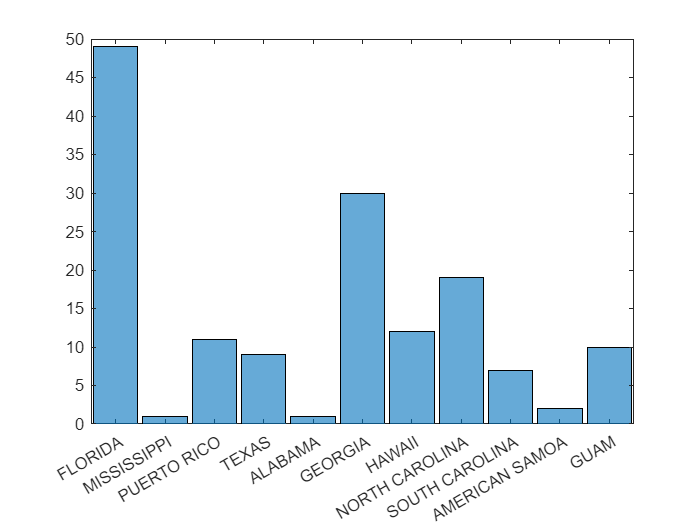

histogram(df.State)

As we can see, most hurricanes were reported in Florida, followed by Georgia and North Carolina.

stm= groupcounts(df, 'Month')

stm = 8×3 table
        Month        GroupCount    Percent
    _____________    __________    _______

    {'April'    }         3         1.9868
    {'August'   }        22          14.57
    {'December' }         1        0.66225
    {'July'     }         3         1.9868
    {'March'    }         1        0.66225
    {'May'      }         4          2.649
    {'October'  }        63         41.722
    {'September'}        54         35.762


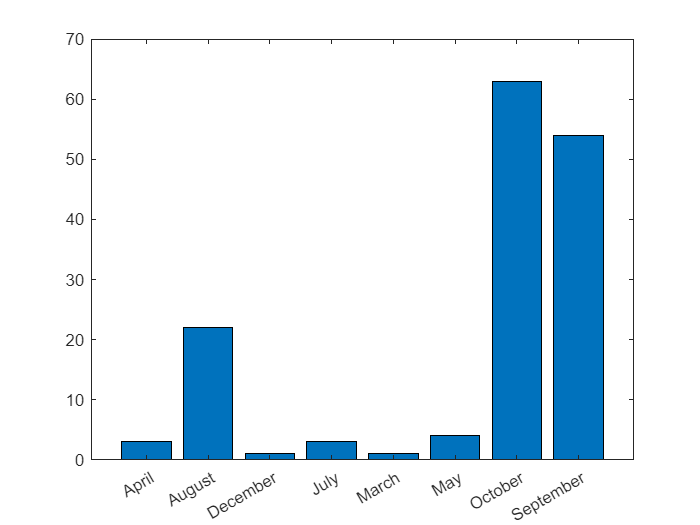

bar(stm.Month,stm.GroupCount,'DisplayName','stm.GroupCount')

month= {'April', 'May', 'June', 'July', 'August', 'September', 'October', 'November', 'December'};
val = [3,4,0,3,22,54,63,0,1];

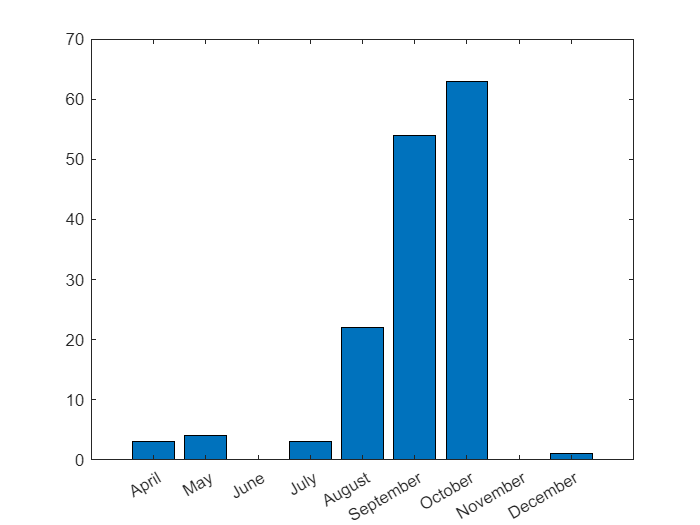

bar(val)
xticklabels(month)

As we can see, most hurricanes occurred in the month September and October.

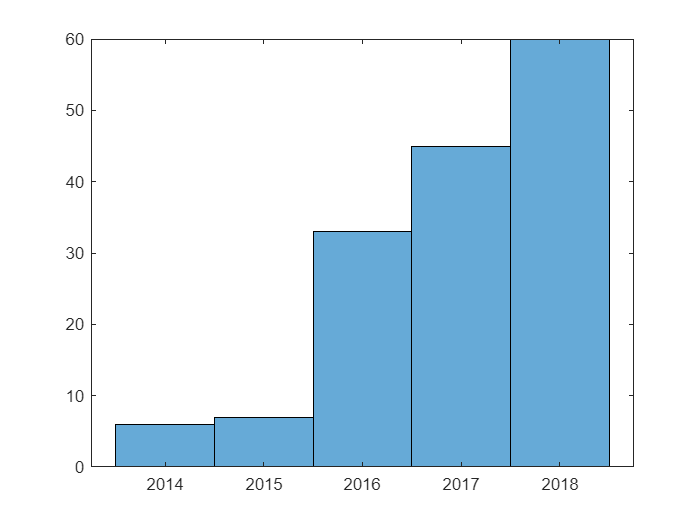

histogram(df.Year)

## Casualty

df

df = 151×17 table
        State         Year        Month        Event_Type      Begin_Date_Time       Timezone        End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost                                                                                                                                                                                                                                                                                                                                                                                                                                                                                     

df.Injuries = df.Injuries_Direct + df.Injuries_Indirect;
df.Deaths = df.Deaths_Direct + df.Deaths_Indirect;
df

df = 151×19 table
        State         Year        Month        Event_Type      Begin_Date_Time       Timezone        End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost                                                                                                                                                                                                                                                                                                                                                                                                                                                                                     

sum(df.Injuries)

ans = 158

sum(df.Deaths)

ans = 77

### Which year there were more deaths?

stm= groupsummary(df, 'Year', 'sum', "Deaths")

stm = 5×3 table
    Year    GroupCount    sum_Deaths
    ____    __________    __________

    2014         6             0    
    2015         7             5    
    2016        33             6    
    2017        45            28    
    2018        60            38    


sortrows(df, "Deaths", "descend")

ans = 151×19 table
        State         Year        Month            Event_Type           Begin_Date_Time      Timezone        End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost                                                                                                                                                                                                                                                                                                                                                                                                                                                                            

As we can see, the hurricane 'Michael' in 2018 in Florida caused a significant damage to life and property.

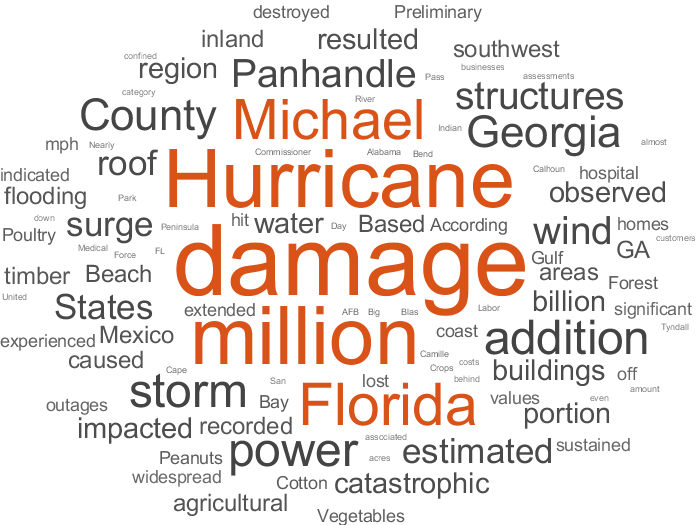

 wordcloud(df.Episode_Narrative(53))

## Property Cost

stp= groupsummary(df, 'Year', 'sum', "Property_Cost")

stp = 5×3 table
    Year    GroupCount    sum_Property_Cost
    ____    __________    _________________

    2014         6              9.7e+05    
    2015         7            3.156e+07    
    2016        33           8.1569e+08    
    2017        45           5.7879e+09    
    2018        60           6.1347e+09    


sts= groupsummary(df, "State", 'sum', "Property_Cost")

sts = 11×3 table
        State         GroupCount    sum_Property_Cost
    ______________    __________    _________________

    FLORIDA               49           5.4005e+09    
    MISSISSIPPI            1                    0    
    PUERTO RICO           11                5e+06    
    TEXAS                  9           4.1411e+09    
    ALABAMA                1             2.94e+06    
    GEORGIA               30           1.5162e+09    
    HAWAII                12                    0    
    NORTH CAROLINA        19           1.4662e+09    
    SOUTH CAROLINA         7           2.0704e+08    
    AMERICAN SAMOA         2                    0    
    GUAM                  10            3.186e+07    


stp18= groupsummary(data_18_hurricane, 'State', 'sum', "Property_Cost")

stp18 = 6×3 table
          State           GroupCount    sum_Property_Cost
    __________________    __________    _________________

    {'ALABAMA'       }         1             2.94e+06    
    {'FLORIDA'       }        14             3.15e+09    
    {'GEORGIA'       }        22           1.5162e+09    
    {'HAWAII'        }        12                    0    
    {'NORTH CAROLINA'}         9           1.4655e+09    
    {'SOUTH CAROLINA'}         2                40000    


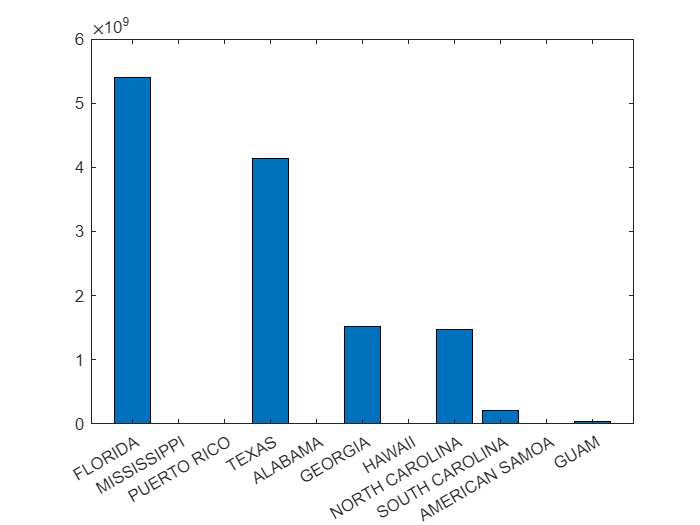

bar(sts.State,sts.sum_Property_Cost,'DisplayName','sts.sum_Property_Cost')